# Lab13: 

Team1: Dmitry Shadrin, Eugenii Israelit @Skoltech

Part I. 

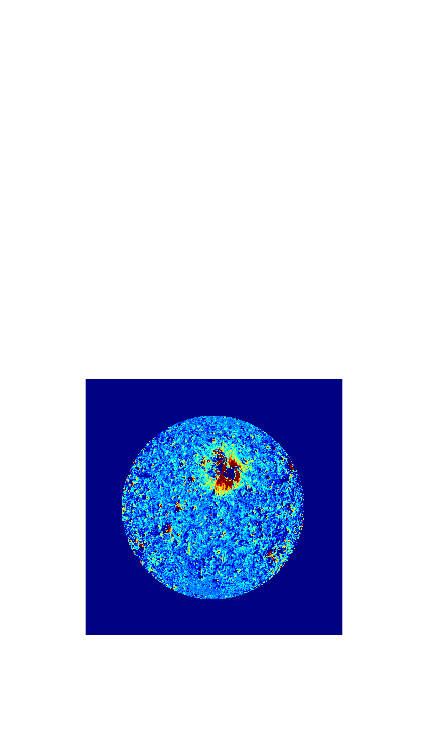

clc; clear; close all;
addpath('functions/');
addpath('week 7/lab13');
D = importdata('data/ro.mat');
B = importdata('data/phi.mat');

Im1 = importdata('data/Image1.mat');
Im2 = importdata('data/Image2.mat');
Im3 = importdata('data/Image3.mat');
Im4 = importdata('data/Image4.mat');

B1 = importdata('data/borders1.mat');
B2 = importdata('data/borders2.mat');
B3 = importdata('data/borders3.mat');
B4 = importdata('data/borders4.mat');

figure;
imshow(Im1,[-100 300]);
colormap jet; 

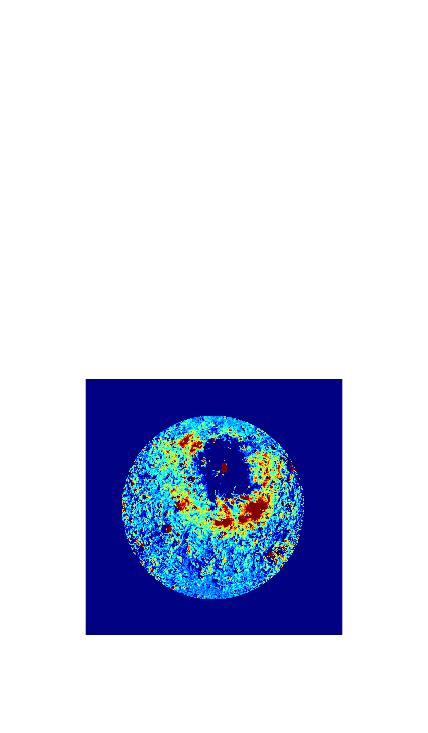


figure;
    imshow(Im2,[-100 300]);
    colormap jet; 

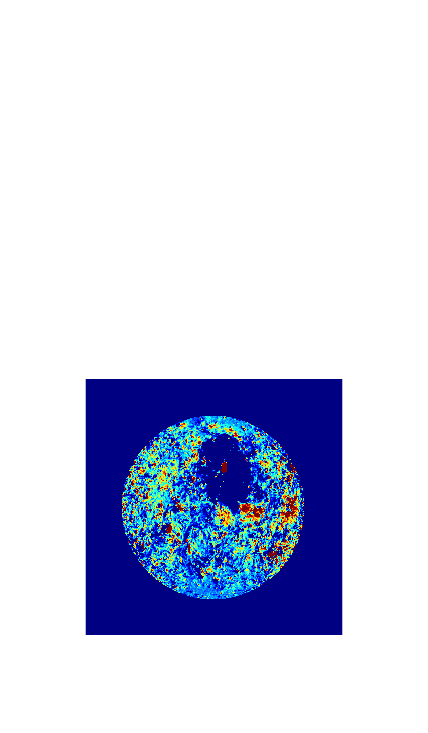


figure;
    imshow(Im3,[-100 300]);
    colormap jet; 

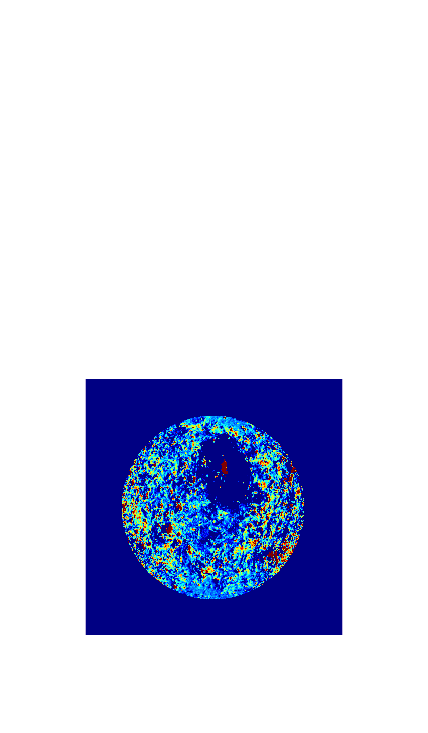


figure;
    imshow(Im4,[-100 300]);
    colormap jet; 

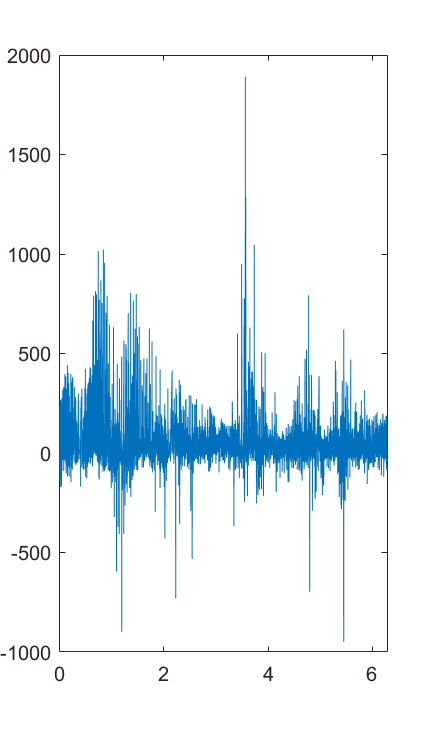



ind = find( D > B1(1) & D < B1(2) );
front = Im1(ind);
BFront = B(ind);

[tmp index] = sort(BFront);
front = front(index);
BFront = BFront(index);
plot(BFront, front);
xlim([0, 2*pi]);

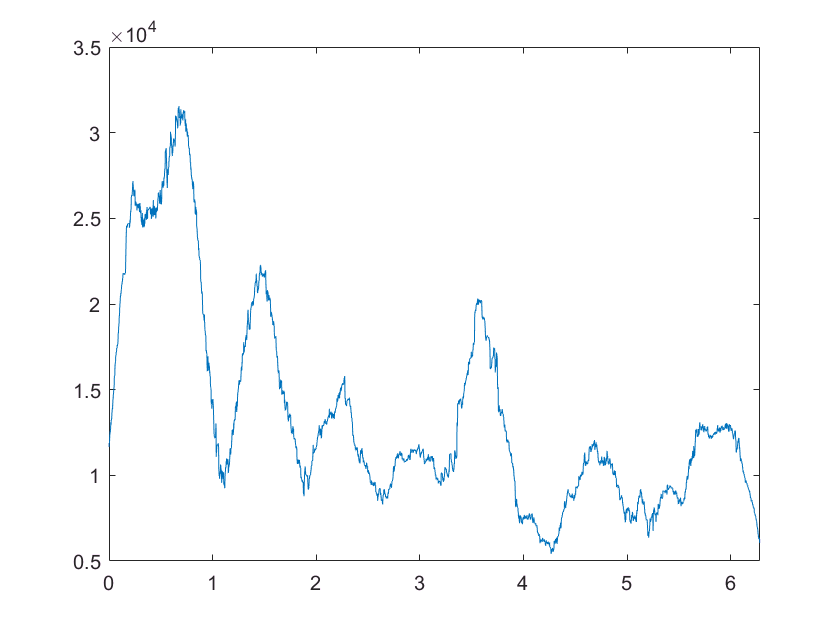


n = length(BFront);
FrontSum = zeros(1,n);

for i=1:n
    ind=find(BFront > BFront(i)-pi/16 & BFront < BFront(i)+pi/16);     
    FrontSum(i) = sum(front(ind));
end

figure;
    plot(BFront,FrontSum);
    xlim([0, 2*pi]);

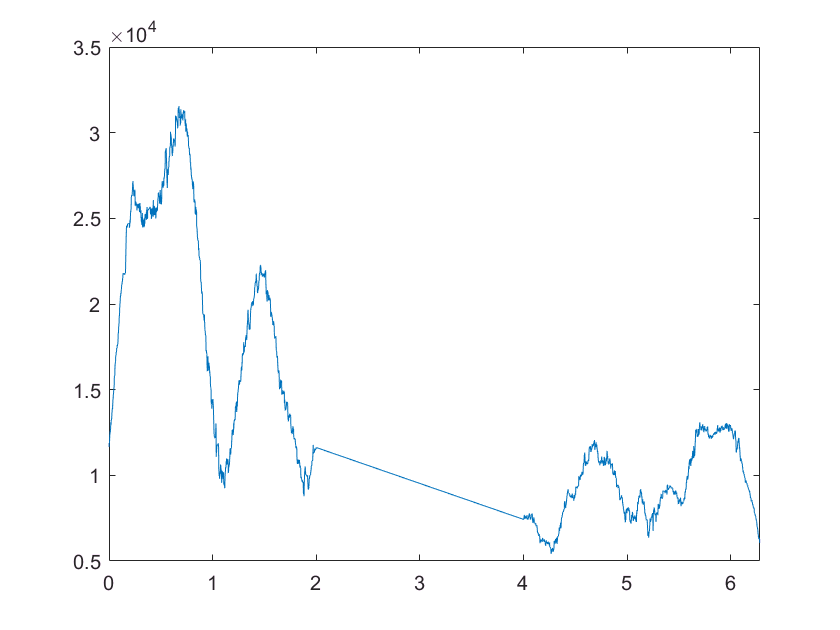


%    ind = find( D > B1(1) & D < B1(2) );
fInd = find(BFront < 2 | BFront > 4);
Bcut = BFront(fInd);
Dcut = FrontSum(fInd);

figure;
    plot(Bcut,Dcut);
    xlim([0, 2*pi]);

    
front(front < 0 ) = 0;


